addpath(genpath('~/Documents'));


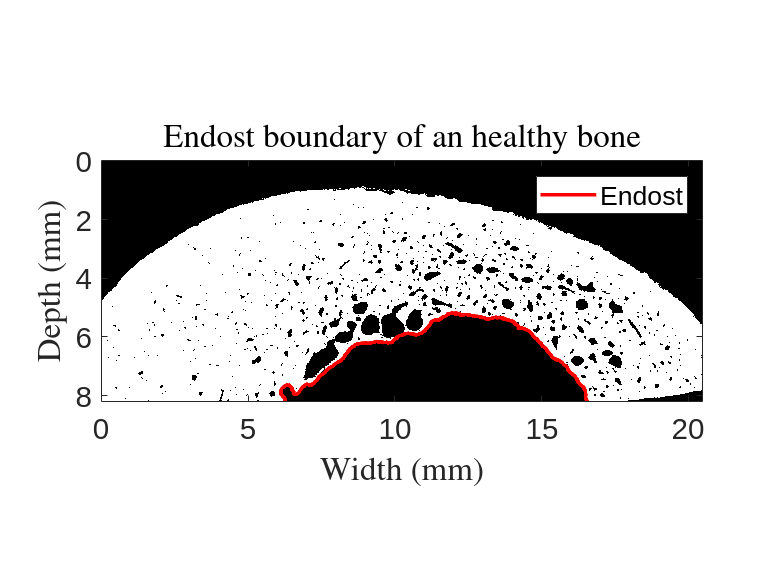

bones = {'245D', '227G', '267G'};
slices = {{1134, 3195, 3852, 5511}, {2002, 3595, 5614, 6721}, {1700, 3410, 5478, 6716}}; 

i = 1; j = 1;
dirname = '~/Documents/BoneRugosity/2_ParametersDefinition/BoneImage';
file = sprintf('SAMPLE_%s_SLICE_%04d.bmp', bones{b}, slices{s});
filename = fullfile(dirname, file);

bone_bmp = imread(filename); 
threshold = graythresh(bone_bmp); % Find an automatic threshold
binaryImage = imbinarize(bone_bmp, threshold);

% BOUNDARIES COMPUTATION
if i == 1 && j ~=1
    if j == 2 || j == 4
        angle = -10;
    elseif j == 3
        angle = -15;
    end
    binaryImage = imrotate(binaryImage, angle,'bilinear','loose');
    binaryImage = binaryImage(1:find(...
    sum(binaryImage(: , 1: size(binaryImage, 2)/2),2) > 10, 1, 'last'), :);
end 

segmented = false;
boundaryEndost = ExtractBoundary(binaryImage);
figure
stepXRay = 0.009; % Step of the X-Ray image (mm)
X = 0:stepXRay:size(binaryImage, 2)*stepXRay; %X = X - mean(X);
Z = flipud(0:stepXRay:size(binaryImage, 1)*stepXRay);
imagesc(X, Z, binaryImage)
hold on
plot(boundaryEndost(1,:)*stepXRay, boundaryEndost(2,:)*stepXRay, 'r', 'LineWidth', 2)
xlabel('Width (mm)', 'Interpreter', 'latex',  'FontSize', 22);
ylabel('Depth (mm)', 'Interpreter', 'latex',  'FontSize', 22);
hold off
axis image
colormap(gray)
title({'Endosteal boundary a bone sample'}, 'Interpreter', 'latex',  'FontSize', 22)
legend('Endost')
ax = gca; 
ax.FontSize = 16;

boundaryEndost(2, :) = max(boundaryEndost(2, :)) - boundaryEndost(2, :);

%% COMPUTE FOURRIER TRANSFORM OF THE PROFILE
% Parameters
delta_x = 9e-3;             % Pixel size corresponding to the space step (mm)
Fs = 1/delta_x;             % Sampling frequency (mm-1)
L = size(boundaryEndost, 2);

% Initial profile
profile = boundaryEndost(2, 2:end) * delta_x; % - mean(boundary_endost(2, :));

x = (boundaryEndost(1,:) - boundaryEndost(1,1))*1/Fs;

%% WITH BUILT-IN FUNCTION 

Select the cut off frequency 

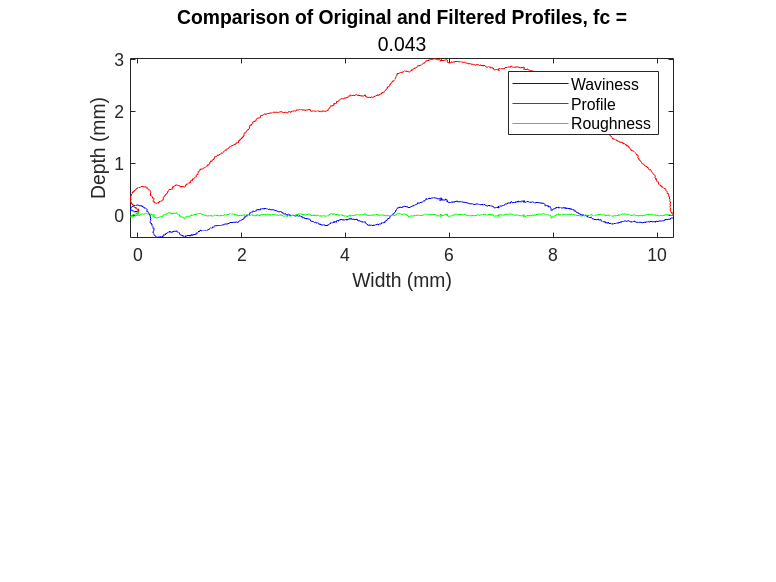

% kc = 2.5e6/(10*3500e3);
kc = 0.043;
waviness = highpass(profile,kc,Fs);
roughness = highpass(profile, 1.25, Fs);

figure
subplot(2,1,1)
plot(x(1, 2:end), waviness, 'b', 'DisplayName', 'Waviness');
hold on
plot(x(1, 2:end), profile, 'r', 'DisplayName', 'Profile');
hold on
plot(x(1, 2:end), roughness, 'g', 'DisplayName', 'Roughness');
title('Comparison of Original and Filtered Profiles, fc =', kc);
xlabel('Width (mm)');
ylabel('Depth (mm)');
legend();

axis equal

f = figure

f =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [927 656 705 529]
       Units: 'pixels'

  Show all properties


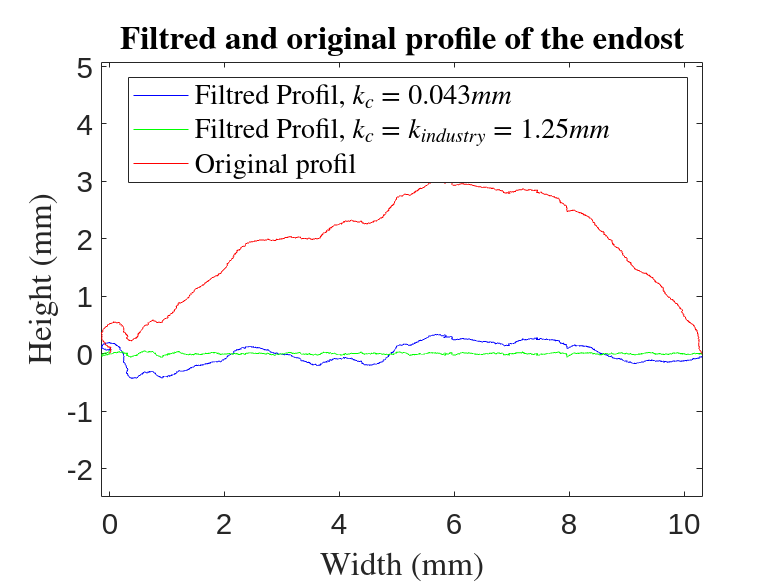

plot(x(1, 2:end), waviness, 'b');
hold on
plot(x(1, 2:end), roughness, 'g');
hold on
plot(x(1, 2:end), profile, 'r');
% title('\bf Waviness and original profile of the endost', ['$k_c = \frac{k_{\lambda}}{10} = ' sprintf('%.3f', kc) 'mm^{-1}$'], 'Interpreter', 'latex', 'FontSize', 24);
title('\bf Filtred and original profile of the endost', 'Interpreter', 'latex', 'FontSize', 24);
xlabel('Width (mm)', 'Interpreter', 'latex', 'FontSize', 24);
ylabel('Height (mm)', 'Interpreter', 'latex', 'FontSize', 24);
legend('Filtred Profil, $k_c = 0.043 mm$', 'Filtred Profil, $k_c = k_{industry}=1.25mm$', 'Original profil', 'Interpreter', 'latex', 'FontSize', 14)
axis equal
fontsize(f, 'increase') 
ax = gca; 
ax.FontSize = 16;

rms_W = rms(waviness);
format = 'The interface have a rms of %.3f mm and a correlation length of %.3f mm';
fprintf(format, rms_W, ComputeCorr(waviness, 0.01));

The interface have a rms of 0.200 mm and a correlation length of 1.260 mm

frequencies = logspace(log10(1e-3), log10(50), 50);

SigFreqBone = 2.5e6/3200e3;        % Frequency (mm-1) that corresponds to the wavelenght in bone 

frequencies_lambda = [SigFreqBone, SigFreqBone/10, SigFreqBone/100, SigFreqBone*10];
parameters = zeros(3, length(frequencies));

for i = 1 : length(frequencies)
    [profile, filtredProfil, xProfile] = FilterProfil(binaryImage, frequencies(i));
    % parameters(1, i) = rms(filtredProfil);
    % parameters(2, i) = trapz(filtredProfil);
    parameters(3, i) = mean(filtredProfil);
end
frequenciesFreq = frequencies/SigFreqBone;

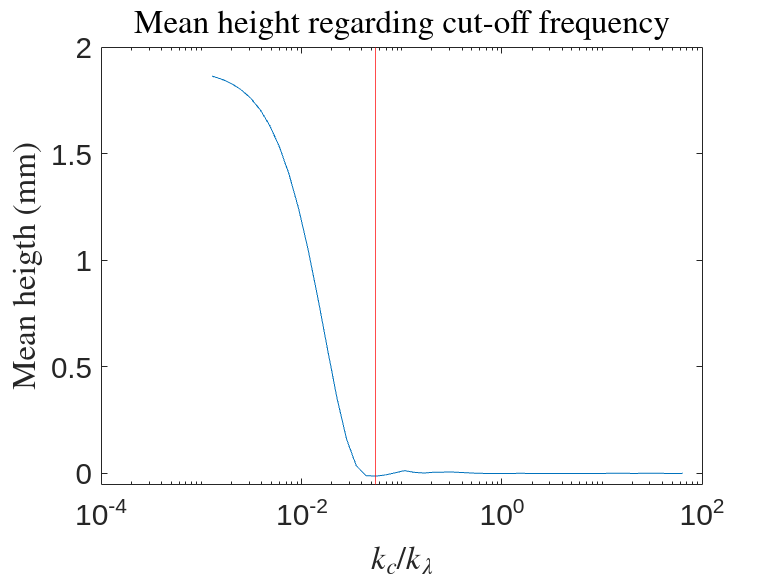

b = frequencies(find(gradient(parameters(3,:)./gradient(frequencies)) >= 0, 1));
c = frequenciesFreq(find(gradient(parameters(3,:)./gradient(frequenciesFreq)) >= 0, 1));
% Expression of the frequencies regarding the frequency that corresponds to
% the bone wavelength. 

figure
% subplot(1,2,1)
% semilogx(frequencies, parameters(1, :));
% hold on 
% xline(fc/SigFreqBone, 'r');
% xline(1.25/SigFreqBone, 'b');
% hold off
% title('Evolution of the RMS regarding the cutt off frequency');
% xlabel('Cutt off frequency expressed in bone wavelength');
% ylabel('RMS (mm)')Freq;

% subplot(1,2,2)
semilogx(frequenciesFreq, parameters(3, :));
hold on 
xline(c, 'r');
hold off
title('Mean height regarding cut-off frequency', 'Interpreter', 'latex', 'FontSize', 24);
ylabel('Mean heigth (mm)', 'Interpreter', 'latex', 'FontSize', 22);
xlabel('$k{_c}/k{_\lambda}$', 'Interpreter', 'latex', 'FontSize', 22);
ylim([-0.05,2])
ax = gca; 
ax.FontSize = 16;

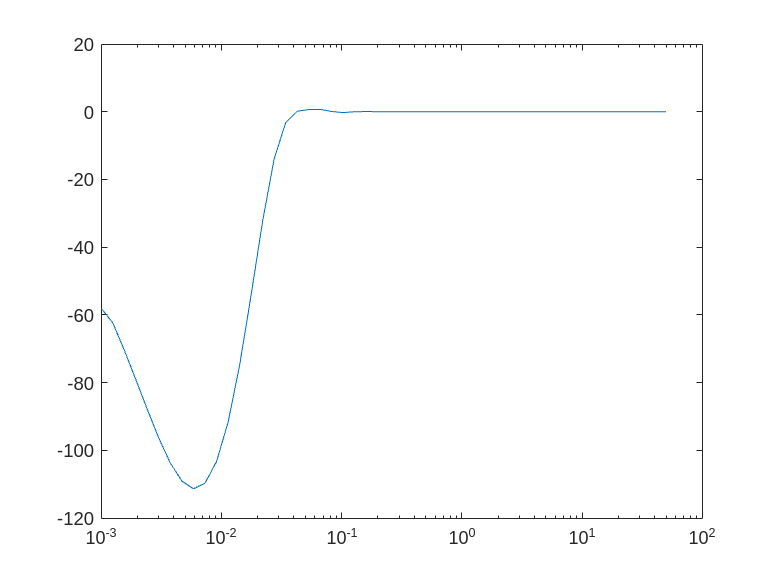

% legend('mean heigth', '$$k_c = \frac{k_{\lambda}}{10} \mathrm{(mm^{-1})}$$', 'Interpreter', 'latex'); %'$k_c = k_{industry} = 1.25 (mm^{-1})$', 
figure
semilogx(frequencies, gradient(parameters(3, :))./gradient(frequencies))